## Steady-State Errors

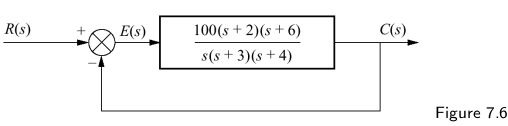

Find the steady state errors for inputs $5u(t)$, $5tu(t)$ and $\frac{5}{2}t^2u(t)$

G=zpk([-2 -6],[0 -3 -4],100)

G =
 
  100 (s+2) (s+6)
  ---------------
   s (s+3) (s+4)
 
Continuous-time zero/pole/gain model.
Model Properties


G_cl=feedback(G,1)

G_cl =
 
        100 (s+6) (s+2)
  ----------------------------
  (s+98.91) (s+6.097) (s+1.99)
 
Continuous-time zero/pole/gain model.
Model Properties


pole(G_cl)

ans =   -98.9135
   -1.9899
   -6.0966


**5 unit step input case**

For $r(t)=5u(t)$:


$$e_{ss} =  \lim_{s \rightarrow 0} s \, \frac{5/s}{1+ G(s)} = \frac{5}{1 + \lim_{s \rightarrow 0} G(s)}$$


but $\lim_{s \rightarrow 0} G(s)=\infty$ so $e_\textit{ss}=0$ in this case.

In matlab we can numerically evaluate the value of a transfer function for a given value of $s$ with the matlab command $\texttt{evalfr}$.

evalfr(G,0)

ans = Inf

As a check. let's see what the DC gain of the closed loop transfer function $G_{cl}$(s) is: 

evalfr(G_cl,0)

ans = 1.0000

So a 5 unit step input to the closed loop system results in a 5 unit step output. Hence there is zero error.

**5 unit ramp input case**

For $r(t)=5tu(t)$ we have $R(s)=\frac{5}{s^2}$ so we get:


$$e_{ss}  = \lim_{s \rightarrow 0}   \frac{s(5/s^2)}{1+ G(s)} =\lim_{s \rightarrow 0} \frac{5}{s + sG(s)} = \frac{5}{\lim_{s \rightarrow 0} s G(s)}$$


s=tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


s*G

ans =
 
  100 s (s+2) (s+6)
  -----------------
    s (s+3) (s+4)
 
Continuous-time zero/pole/gain model.
Model Properties


evalfr(s*G,0)

ans = Inf

This is *not* the correct answer. We should simplify the transfer function for $sG(s)$ by cancelling the pole and zero to obtain the transfer function:

sG=zpk([-2 -6],[-3 -4],100)

sG =
 
  100 (s+2) (s+6)
  ---------------
    (s+3) (s+4)
 
Continuous-time zero/pole/gain model.
Model Properties


evalfr(sG,0)

ans = 100

ess_ramp=5/evalfr(sG,0)

ess_ramp = 0.0500

myRamp=zpk([],[0 0],5)

myRamp =
 
   5
  ---
  s^2
 
Continuous-time zero/pole/gain model.
Model Properties


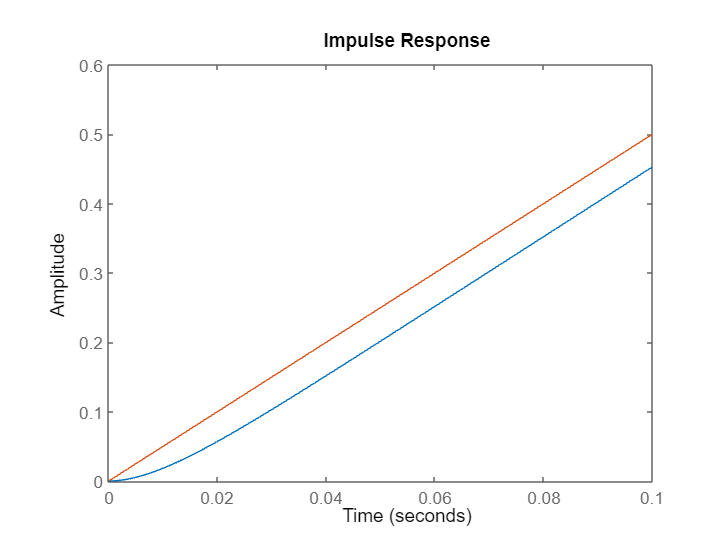

impulse(G_cl*myRamp,myRamp,0.1)

Doing the above symbolically:

syms s G R G_e E
G(s)=100*(s+2)*(s+6)/(s*(s+3)*(s+4))

$$G(s) = \frac{\left(100\,s+200\right)\,\left(s+6\right)}{s\,\left(s+3\right)\,\left(s+4\right)}$$

G_e(s)=simplifyFraction(1/(1+G(s)))

$$G\_e(s) = \frac{s\,\left(s+3\right)\,\left(s+4\right)}{s^{3}+107\,s^{2}+812\,s+1200}$$

collect(s*G(s))

$$ans = \frac{100\,s^{2}+800\,s+1200}{s^{2}+7\,s+12}$$

limit(G(s),s,0)

$$ans = \mathrm{NaN}$$

subs(s*G(s),s,0)

$$ans = 100$$

limit(s*G(s),s,0)

$$ans = 100$$

Error for a unit ramp is given by $\frac{1}{\lim_{s\rightarrow 0}sG(s)}$

UnitRampError=1/limit(s*G(s),s,0)

$$UnitRampError = \frac{1}{100}$$

FiveUnitRampError = 5*UnitRampError

$$FiveUnitRampError = \frac{1}{20}$$

Let's plot the error function to confirm that we get a steady state error of approximately $\frac{1}{20}=0.05$:

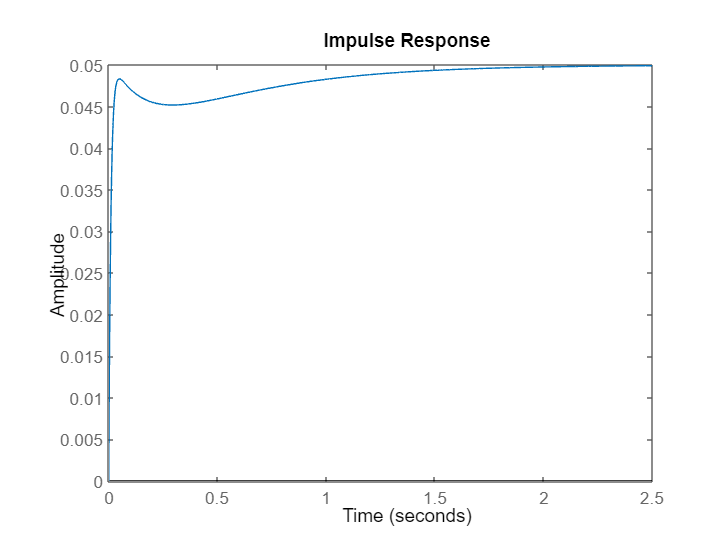

impulse((1-G_cl)*myRamp)

**For the 5/2 unit parabola case:**

For $r(t)=\frac{5}{2}t^2u(t)$ we have $R(s)=\frac{5}{s^3}$ so we get:

Error for a unit parabola $\frac{1}{s^3}$ is given by $\frac{1}{\lim_{s\rightarrow 0}s^2G(s)}$

subs(s^2*G(s),0)

$$ans = 0$$

UnitParaError=1/subs(s^2*G(s),0)

$$UnitParaError = \infty$$

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


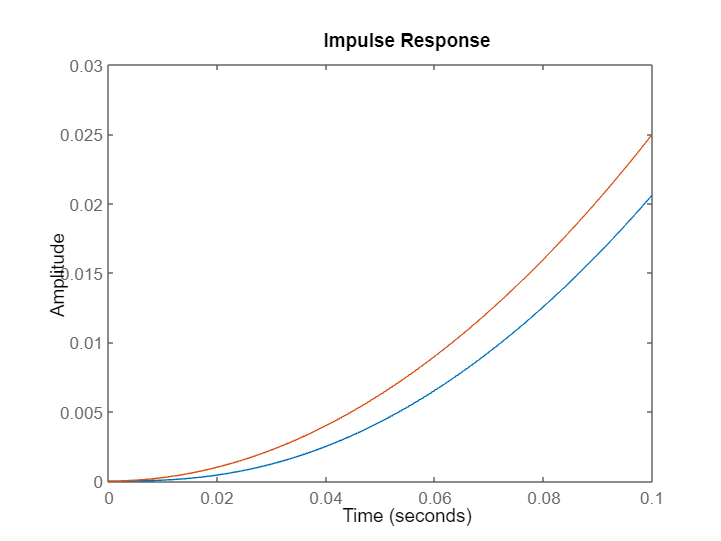

impulse(G_cl*5/s^3,5/s^3,.1)

Let's plot the error function:

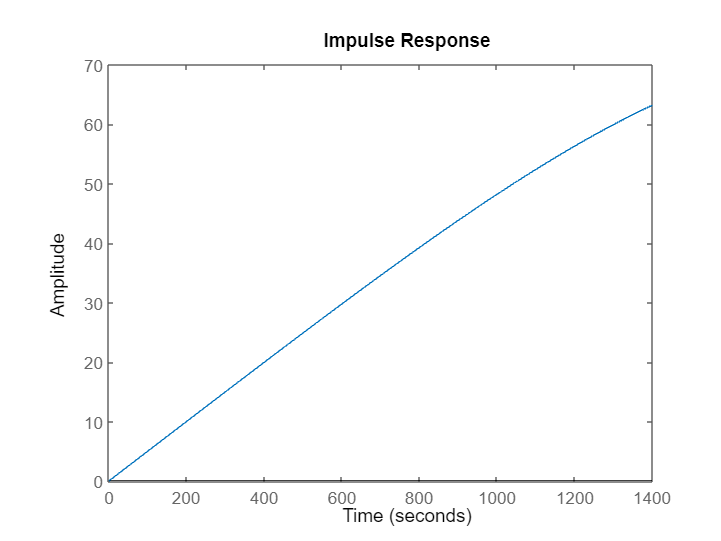

impulse(5/s^3-G_cl*5/s^3)

OK. So it grows without bound and goes to $\infty$ in a linear fashion.

For system below, find value of K such there is 10% error in steady state.

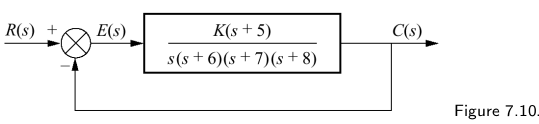

syms s G K
G(s)=K*(s+5)/(s*(s+6)*(s+7)*(s+8))

$$G(s) = \frac{K\,\left(s+5\right)}{s\,\left(s+6\right)\,\left(s+7\right)\,\left(s+8\right)}$$

s*G(s)

$$ans = \frac{K\,\left(s+5\right)}{\left(s+6\right)\,\left(s+7\right)\,\left(s+8\right)}$$

K_v=limit(s*G(s),s,0)

$$K\_v = \frac{5\,K}{336}$$

ess=1/K_v==0.1

$$ess = \frac{336}{5\,K}=\frac{1}{10}$$

solve(ess,K)

$$ans = 672$$

Let's do a simulation to confirm:

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


K=672

K = 672

G=K*(s+5)/(s*(s+6)*(s+7)*(s+8))

G =
 
           672 s + 3360
  ------------------------------
  s^4 + 21 s^3 + 146 s^2 + 336 s
 
Continuous-time transfer function.
Model Properties


G_cl=feedback(G,1)

G_cl =
 
               672 s + 3360
  --------------------------------------
  s^4 + 21 s^3 + 146 s^2 + 1008 s + 3360
 
Continuous-time transfer function.
Model Properties


impulse(1/s^2,4)
hold

Current plot held


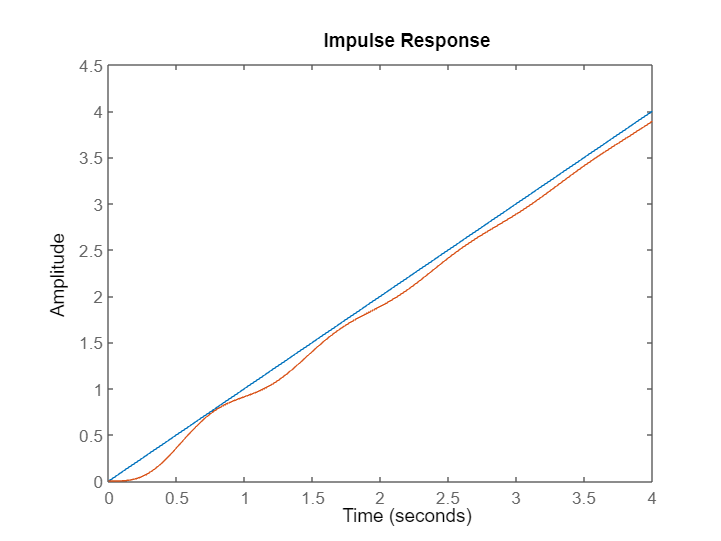

Current plot released


impulse(G_cl/s^2,4)
hold

What would a system tracking a parabolic input with constant error look like?

Consider the system:

G=(s+1)/(s^2*(s+20))

G =
 
     s + 1
  ------------
  s^3 + 20 s^2
 
Continuous-time transfer function.
Model Properties


K=60

K = 60

G_cl=feedback(K*G,1)

G_cl =
 
         60 s + 60
  ------------------------
  s^3 + 20 s^2 + 60 s + 60
 
Continuous-time transfer function.
Model Properties


impulse(1/s^3,4)
hold

Current plot held


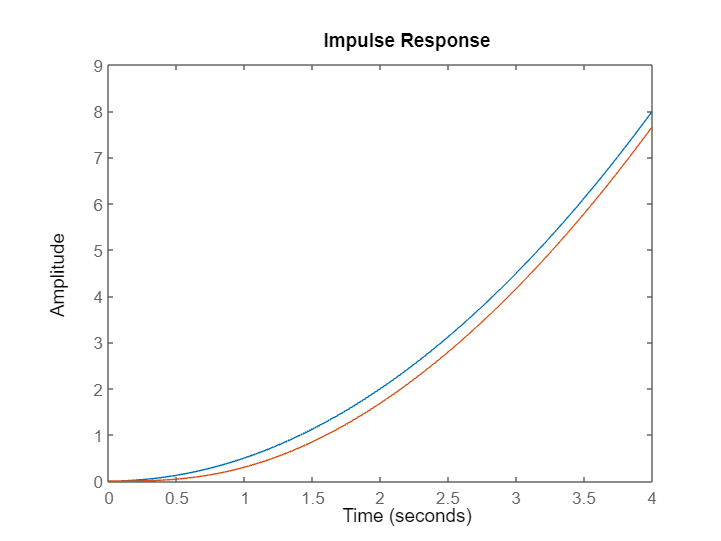

Current plot released


impulse(G_cl/s^3,4)
hold

Consider the system:

Find value of K such there is 10% error in steady state.

The system is Type 1 so in this case it tracks steps with zero error but will have a constant error for ramps (provided $K$ is chosen so that the system is stable).

In this case the static error constant is:


$$K_v = \lim_{s \rightarrow 0} sG(s)$$


K_v=evalfr((s+5)/((s+6)*(s+7)*(s+8)),0)

K_v = 0.0149

In this case the steady state error due to a ramp input $tu(t)$ is:

 
$$e_\textit{ss}=\frac{1}{K_v}\\
\ \        = \frac{1}{\frac{5K}{336}}=0.1\\
K=\frac{3360}{5}\\
\ \ = 672$$


K=672

K = 672

G=K*(s+5)/(s*(s+6)*(s+7)*(s+8))

G =
 
           672 s + 3360
  ------------------------------
  s^4 + 21 s^3 + 146 s^2 + 336 s
 
Continuous-time transfer function.
Model Properties


G_cl=feedback(G,1)

G_cl =
 
               672 s + 3360
  --------------------------------------
  s^4 + 21 s^3 + 146 s^2 + 1008 s + 3360
 
Continuous-time transfer function.
Model Properties


impulse(1/s^2,10)
hold

Current plot held


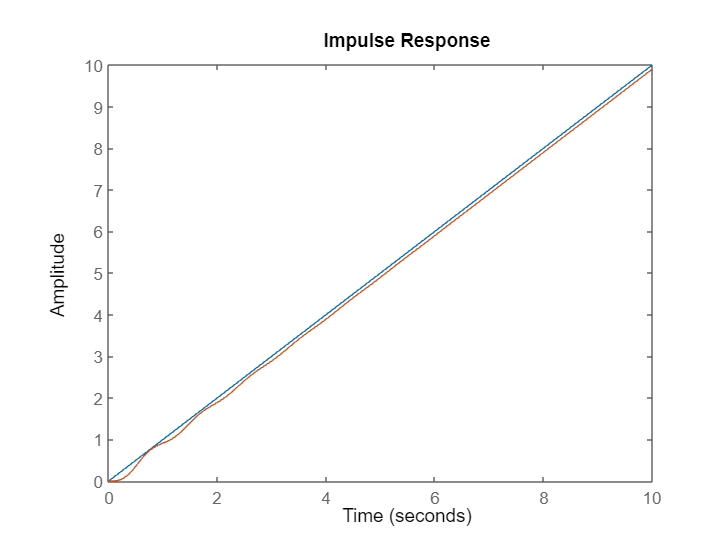

Current plot released


impulse(G_cl/s^2,10)
hold

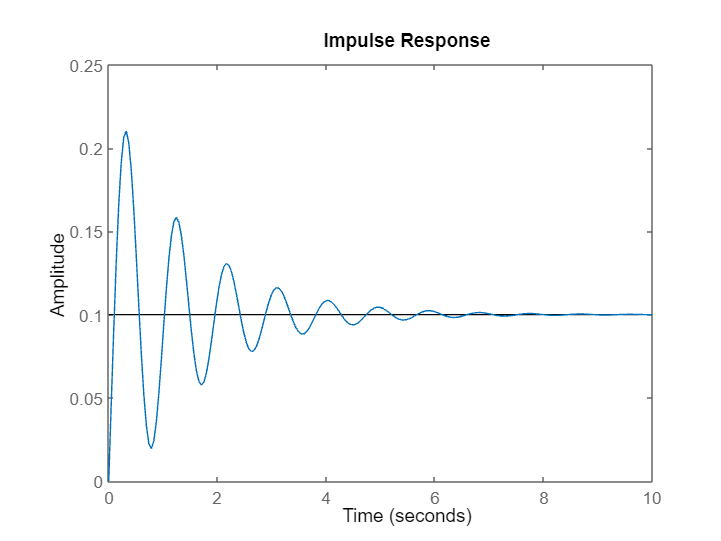

impulse(1/s^2-G_cl/s^2,10)